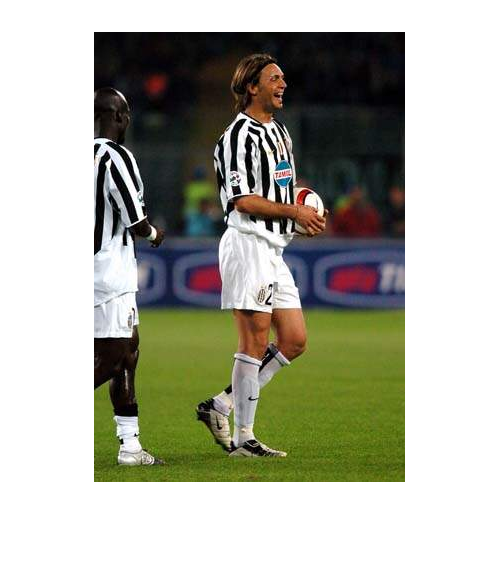

im = imread("juventus\02.jpg");
imshow(im);

f = size(im,1);
c = size(im,2);


## Crear histograma

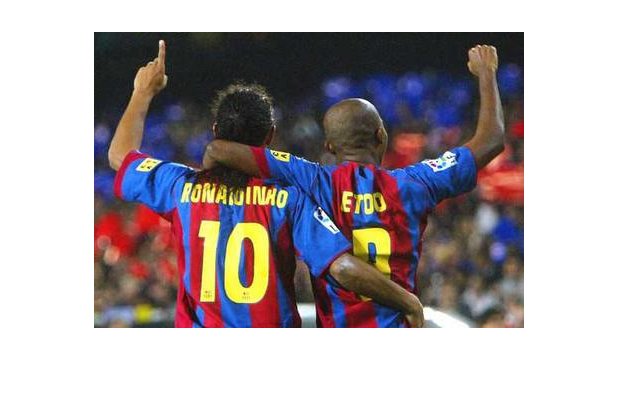

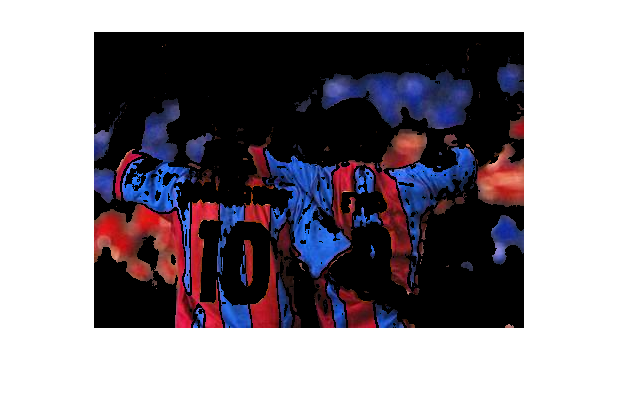

im = imread("barcelona\39.jpg");
filter = crearHistograma(im);


imshow(filter)

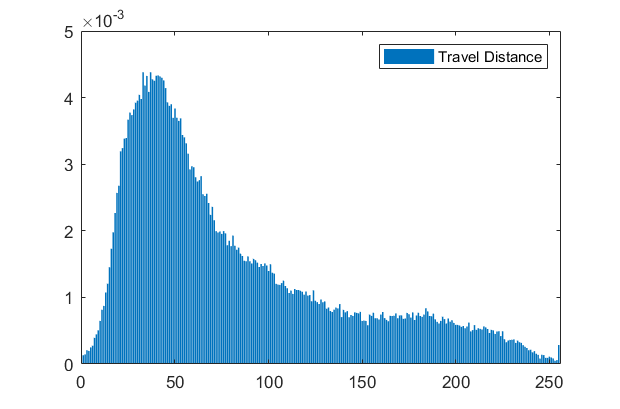


h = imhist(filter);
h = h/sum(h);
h = h(2:256);
   bar(h, 'DisplayName', 'Travel Distance'); 
  legend('show');

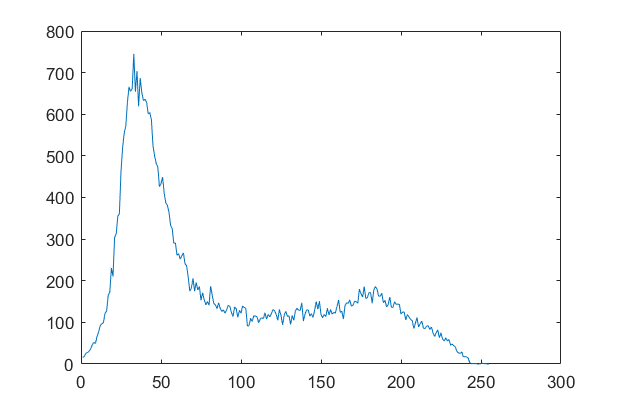



rht = imhist(filter(:,:,1));
subrht = rht(2:256);
plot(subrht);

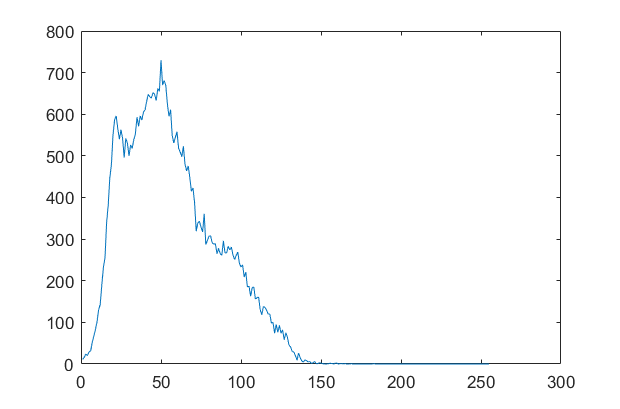

ght = imhist(filter(:,:,2));
subght = ght(2:256);
plot(subght);

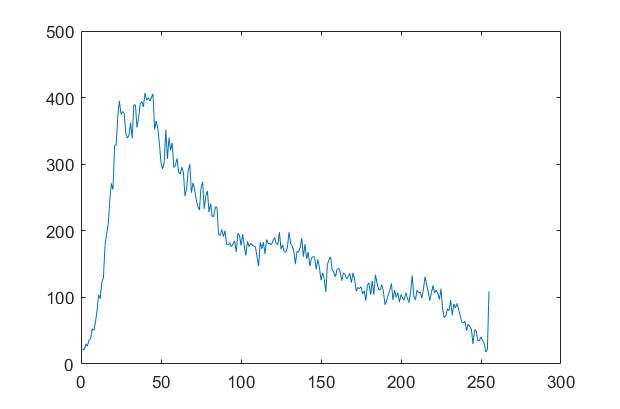

bht = imhist(filter(:,:,3));
subbht = bht(2:256);
plot(subbht);

imshow(filter);

imshow(im);

## Comparacion

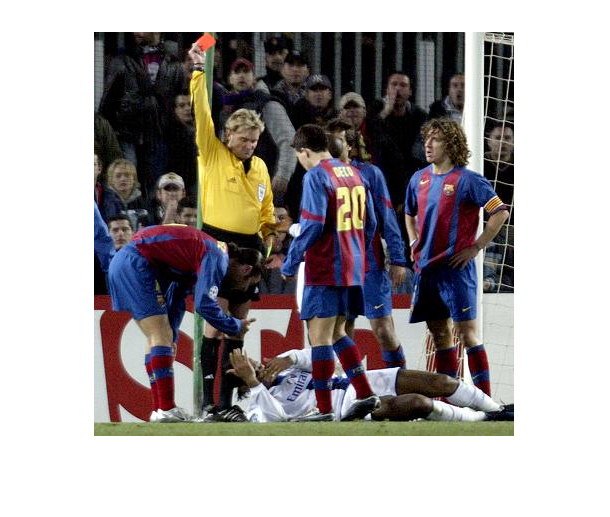

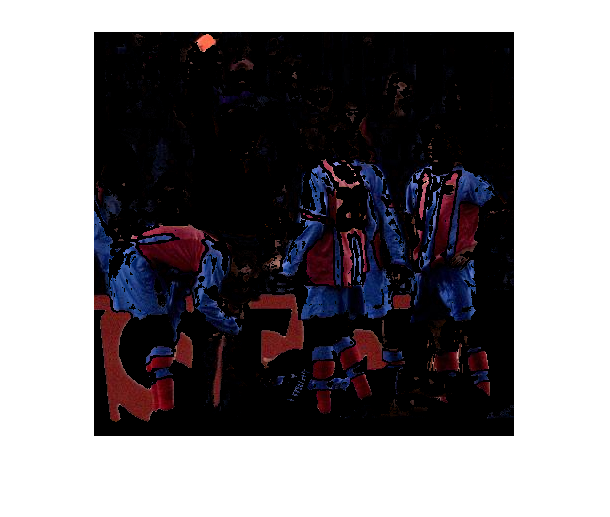

comp = imread('barcelona/01.jpg');
compfilter = crearHistograma(comp);

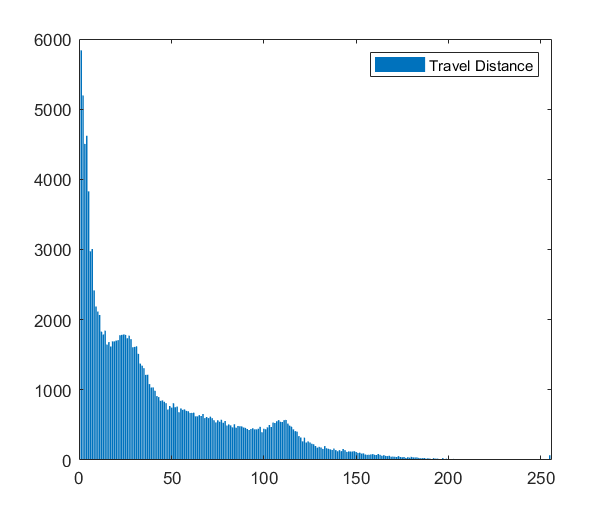



h2 = imhist(compfilter);
h2 = h2/sum(h2);
h2 = h2(2:256);
   bar(h2, 'DisplayName', 'Travel Distance'); 
  legend('show');

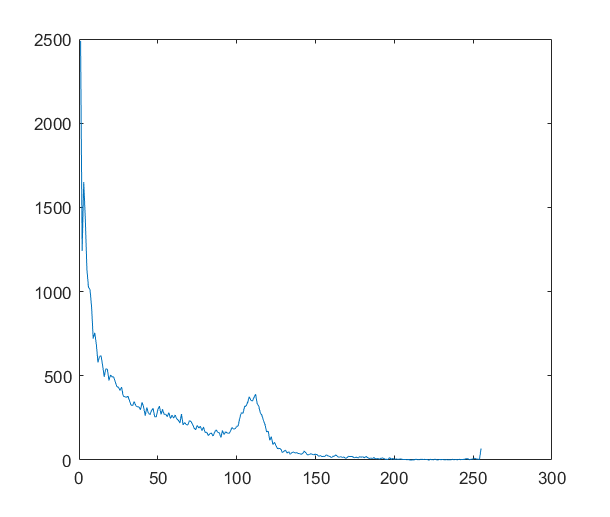




rh = imhist(compfilter(:,:,1));
subrh = rh(2:256);
plot(subrh);

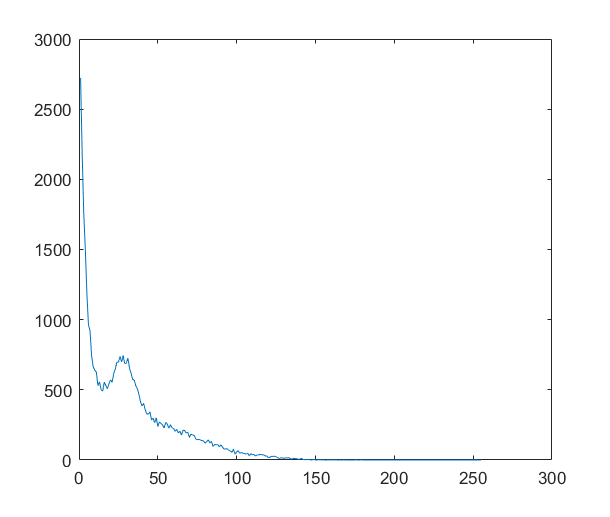

gh = imhist(compfilter(:,:,2));
subgh = gh(2:256);
plot(subgh);

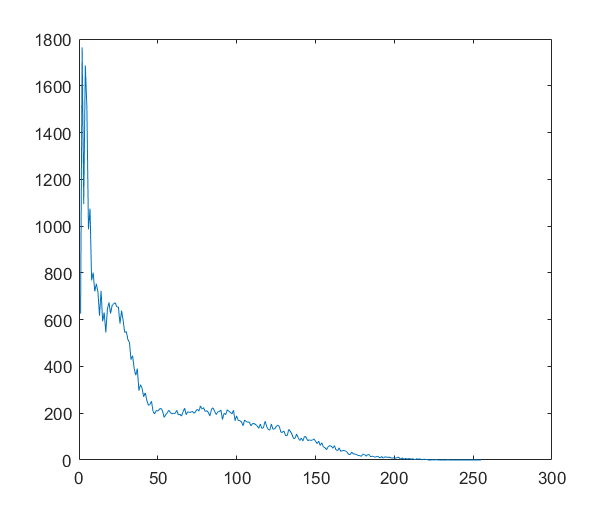

bh = imhist(compfilter(:,:,3));
subbh = bh(2:256);
plot(subbh);

imshow(compfilter);

k = chiDistance(h,h2);
k

k = 6.1670e+04

## Histograma colores separados

function [imFilter] = crearHistograma(ip)
imshow(ip);
f = size(ip,1);
c = size(ip,2);

r=ip(:,:,1);
g=ip(:,:,2);
b=ip(:,:,3);
I=double(r)+double(g)+double(b);
rn=double(r)./I;
gn=double(g)./I;
bn=double(b)./I;
rgbNorm=cat(3,rn,gn,bn);
figure,imshow(rgbNorm),title('Imagen normalizada');
imFilter = uint8(zeros(f,c));
for i=1:f
    for j=1:c
        if rgbNorm(i,j,1) > 0.4
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,3) < 0.3
                    imFilter(i,j,1:3) = ip(i,j,1:3);
                end
            end
        end
        if rgbNorm(i,j,3) > 0.4
            if rgbNorm(i,j,2) < 0.3
                if rgbNorm(i,j,1) < 0.3
                    imFilter(i,j,1:3) = ip(i,j,1:3);
                end
            end
        end
    end
end
imshow(imFilter)
end


function [d] = chiDistance(xi,yi)
d = double(0);
for i=1:255
    up = xi(i) - yi(i);
    down = xi(i) + yi(i);
    d = d + (up^2 / down);
end
end